# **UNIVERSITAT DE BARCELONA**

# **COMPUTER VISION **

# **LAB 11 REPORT**

**JORGE ALEXANDER & EMER RODRIGUEZ FORMISANO**

VLFeat configuration:

clear all;
VLFEAT_DIR = 'VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));
vl_version;

0.9.20


a) 

First, train the model with a subset of categories and load it:

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 600
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 2.85 s
kmeans: Elkan iter 0: energy = 9.84951e+09, dist. calc. = 45714880
kmeans: Elkan iter 1: energy <= 6.79878e+09, dist. calc. = 9990399
kmeans: Elkan iter 2: energy <= 6.55419e+09, dist. calc. = 8512352
kmeans: Elkan iter 3: energy <= 6.45525e+09, dist. calc. = 7216354
kmeans: Elkan iter 4: energy <= 6.39871e+09, dist. calc. = 5853269
kmeans: Elkan iter 5: energy <= 6.36208e+09, dist. calc. = 4577396
kmeans: Elkan iter 6: energy <= 6.33528e+09, dist. calc. = 3768736
kmeans: Elkan iter 7: energy <= 6.31498e+09, dist. calc. = 3201624
kmeans: Elkan iter 8: energy <= 6.29917e+09, dis

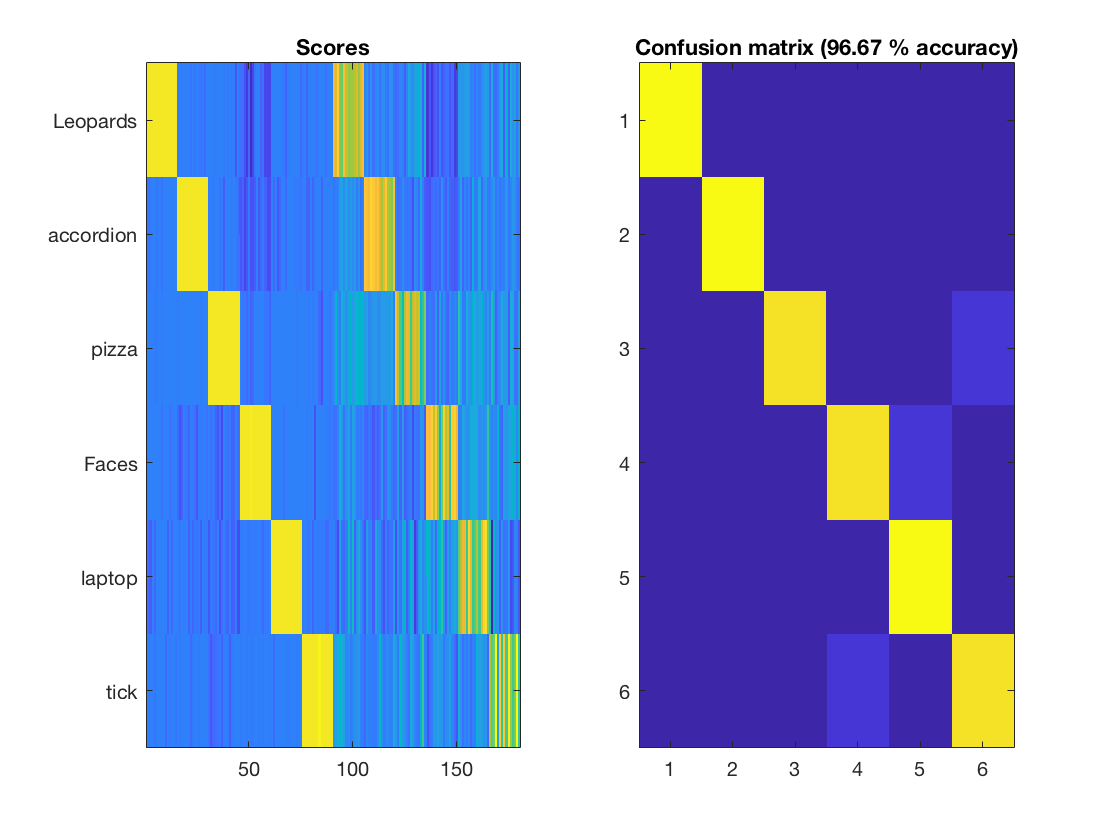

categorySubset = { 'Leopards', 'accordion', 'pizza', 'Faces', 'laptop', 'tick'};
modified_phow_caltech101(categorySubset);

modelPath = fullfile('data','baseline-model.mat');
load(modelPath);

Add a function to train visualize the images in a green framework if the classification is correct and in a red framework if it does not:

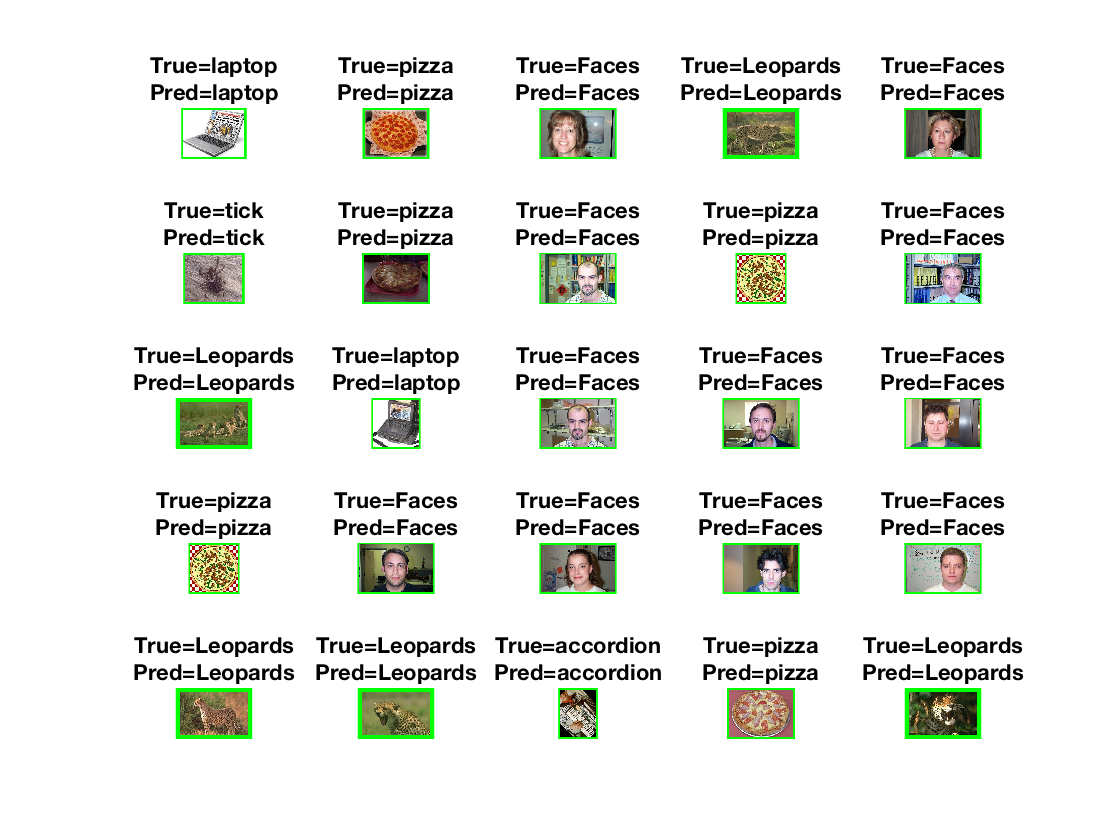

% 
% Choose imageCount random images to classify and draw border around
% 
imageCount = 25;
imageBaseDir = fullfile('data','caltech-101','101_ObjectCategories');
imagePaths = buildImagePaths(imageBaseDir, categorySubset, imageCount);
visualizeImgClass(imagePaths, model);

b) 

*What are the PHOW descriptors?  *

They represent the Pyramid Histogram Of visual Words. 

The function to obtain them is 

%[FRAMES, DESCRS] = vl_phow(IMG)

DESCRS, Each column of DESCRS is the descriptor of the corresponding frame in FRAMES. A descriptor is a 128-dimensional vector of class UINT8.

It represents a 4x4 spatial histogram of gradient orientations, each with 8 different directions, leading to a 4x4x8=128 dimensional vector.

FRAMES(1:2,:) are the x,y coordinates of the center of each descriptor, FRAMES(3,:) is the contrast of the descriptor, as returned by VL_DSIFT() (for colour variant, contranst is computed on the intensity channel). FRAMES(4,:) is the size of the bin of the descriptor.

*What does the Sizes parameter mean? *

It's the scales at which the dense SIFT features are extracted. Each value is used as the spatial bin size in pixels when extracting a dense set of SIFT features from the image.

*What does happen if the Sizes parameter is augmented? *

From the lectures, the code to calculate the phow descriptors:

% step = 5;
% for size=[5,7,10,12]
%     [x,y]=meshgrid(1:step:width, 1:step:height);
%     frames = [x(:)'; y(:)'];
%     frames(3,:) = size/3;
%     frames(4,:) = 0;
%     [frames, descrs] = vl_sift(im, 'Frames', frames);
% end

It can be observed that if the size is increased the size of the bin of the descriptor is increased.				

*What does the Step parameter mean?* 

Step (in pixels) of the grid at which the dense SIFT features are extracted.

*What does happen if the Step parameter is augmented?*

If the step parameter is augmented, then a grid with a lower resolution is created, and less features are extracted.

c) 

*What are the words in the algorithm?* 

*How are they extracted?* 

*What is their dimension?* 

*How their number does affect the accuracy of the results? *

vocabPath = fullfile('data','baseline-vocab.mat'); load(vocabPath); vocab

vocab = 128×600 single matrix
         0   62.1761   10.1183   14.7342   17.2441    2.5616    6.6848   17.7059   13.8952   14.9113   10.6891    7.8350   21.3596   24.2941  112.9375    8.2162   58.0807    7.6709    3.7909    7.3984   20.2830   23.3351   11.8299    5.5197   59.2651   67.1091   10.8526   15.7973   10.0485   10.0253    8.7778   10.7255   23.7059    6.2000    8.6987    7.8118   16.9389   18.8929   15.1039    3.3415    7.9605   12.8664    5.0370   14.7042   20.5740    7.6182    4.4020   16.6894    1.7667   10.0450
         0   15.1479   19.9462    9.0127    6.3146    4.2603    3.7772   13.5163   17.3306   20.6613    0.8348    6.7184   22.7360   25.1123   36.0375    8.2342    7.1863    8.8671    1.4829   10.8618    6.2075   23.9791    8.8707    1.5669   26.7108   34.2727    4.6105   19.4932    9.8058    8.5556   40.4519    7.6863   24.7778   21.3333    6.5449   11.3529   23.7710   17.6786   19.5801    4.6937    3.8092    4.3733   15.2148   60.4859   18.4793   27.5818    6.661

We observe that the vocab consists of 128x600. The 128 represents the 128 dimensions of the sift descriptors generated by *vl_phow*, as explained before. The 600 columns represent one word each. To extract the vocab, k-means is applied to the sift descriptors. Each word of the vocab represents the centre of the k-means clusters found. Observe the classification of 16 Pizzas images below:

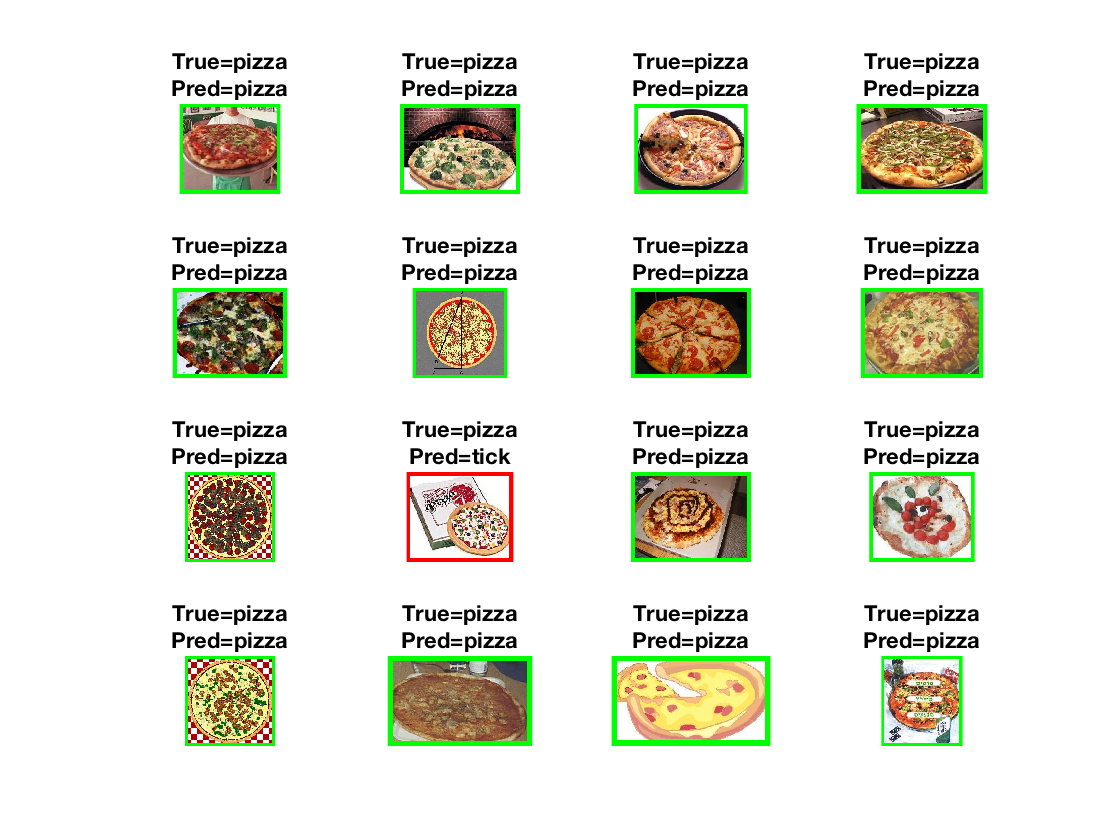

imageCount = 16; 

imagePaths = buildImagePaths(imageBaseDir, {'pizza'}, imageCount); 
visualizeImgClass(imagePaths, model);

Now we attempt to classify the same pizzas with a reduced number of words.

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 6
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 0.02 s
kmeans: Elkan iter 0: energy = 1.88956e+10, dist. calc. = 530091
kmeans: Elkan iter 1: energy <= 1.30718e+10, dist. calc. = 556157
kmeans: Elkan iter 2: energy <= 1.31707e+10, dist. calc. = 298182
kmeans: Elkan iter 3: energy <= 1.22842e+10, dist. calc. = 304227
kmeans: Elkan iter 4: energy <= 1.23343e+10, dist. calc. = 226130
kmeans: Elkan iter 5: energy <= 1.23934e+10, dist. calc. = 155274
kmeans: Elkan iter 6: energy <= 1.24141e+10, dist. calc. = 132288
kmeans: Elkan iter 7: energy <= 1.24162e+10, dist. calc. = 122101
kmeans: Elkan iter 8: energy <= 1.241e+10, dist. calc. = 12

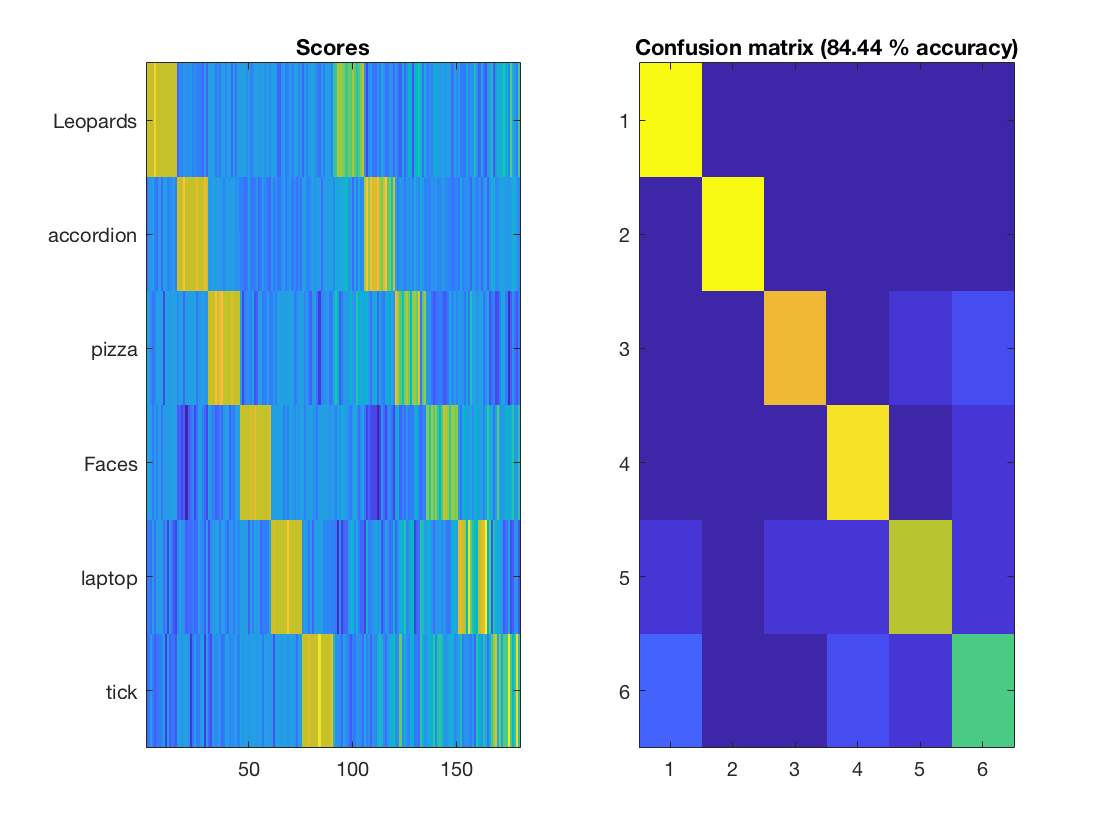

words = length(categorySubset);
modified_phow_caltech101(categorySubset, 'reduced-vocab', words);

A lower accuracy of 84.44% is observed.

modelPath = fullfile('data','reduced-vocab-model.mat'); load(modelPath); model;
vocabPath = fullfile('data','reduced-vocab-vocab.mat'); load(vocabPath); vocab

vocab = 128×6 single matrix
    1.1234   21.4543   11.6557   16.2007   19.2118   33.5356
    0.5161   14.6118   16.2311   17.1164   29.4251   11.7328
    0.7841   14.5942   37.5170   26.0759   16.7001    9.0970
    0.1945   16.7308   27.9172   12.9012   11.3330   22.3647
    0.3987   34.8277   16.1615   11.3468   20.2988   19.1328
    0.8197   14.9710   15.2203   13.3195   29.9366   10.4675
    0.6086    8.8258   28.0213   28.8944   16.2982   15.2576
    0.1987    9.2216   13.9126   16.7263   10.2820   39.3471
    0.2732   25.9330   14.8228   18.3160   31.5388   47.6233
    0.3282   16.4696   20.8563   22.4670   47.4100   16.9878


visualizeImgClass(imagePaths, model);

We observe that although the classification accuracy has gone down, in the sample studied, the majority of pizzas have been classified correctly. There are enough clusters to classify the categories quite well as they are equal in size. We now try with less words than categories. 

kmeans: Initialization = plusplus
kmeans: Algorithm = Elkan
kmeans: MaxNumIterations = 50
kmeans: MinEnergyVariation = 0.000100
kmeans: NumRepetitions = 1
kmeans: data type = float
kmeans: distance = l2
kmeans: data dimension = 128
kmeans: num. data points = 100000
kmeans: num. centers = 2
kmeans: max num. comparisons = 100
kmeans: num. trees = 3

kmeans: repetition 1 of 1
kmeans: K-means initialized in 0.01 s
kmeans: Elkan iter 0: energy = 2.03975e+10, dist. calc. = 186067
kmeans: Elkan iter 1: energy <= 1.45812e+10, dist. calc. = 198487
kmeans: Elkan iter 2: energy <= 1.48907e+10, dist. calc. = 133727
kmeans: Elkan iter 3: energy <= 1.50384e+10, dist. calc. = 148076
kmeans: Elkan iter 4: energy <= 1.54252e+10, dist. calc. = 104992
kmeans: Elkan iter 5: energy <= 1.45443e+10, dist. calc. = 106505
kmeans: Elkan iter 6: energy <= 1.46274e+10, dist. calc. = 103188
kmeans: Elkan iter 7: energy <= 1.47454e+10, dist. calc. = 105485
kmeans: Elkan iter 8: energy <= 1.50074e+10, dist. calc. = 

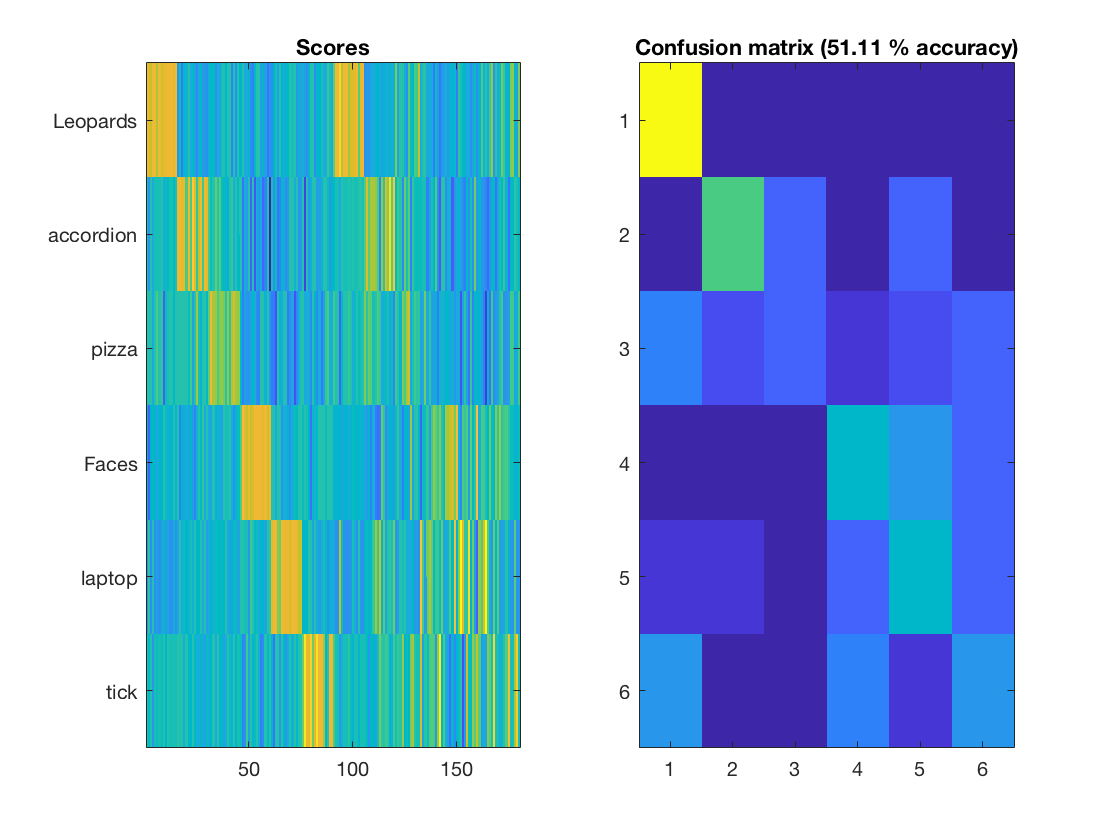

words = 2; modified_phow_caltech101(categorySubset, 'reduced-vocab', words);

We now observe a much lower classification accuracy (51.1%), as there are not enough words to classify each image to the different categories. Let's see whether the same images are classified.

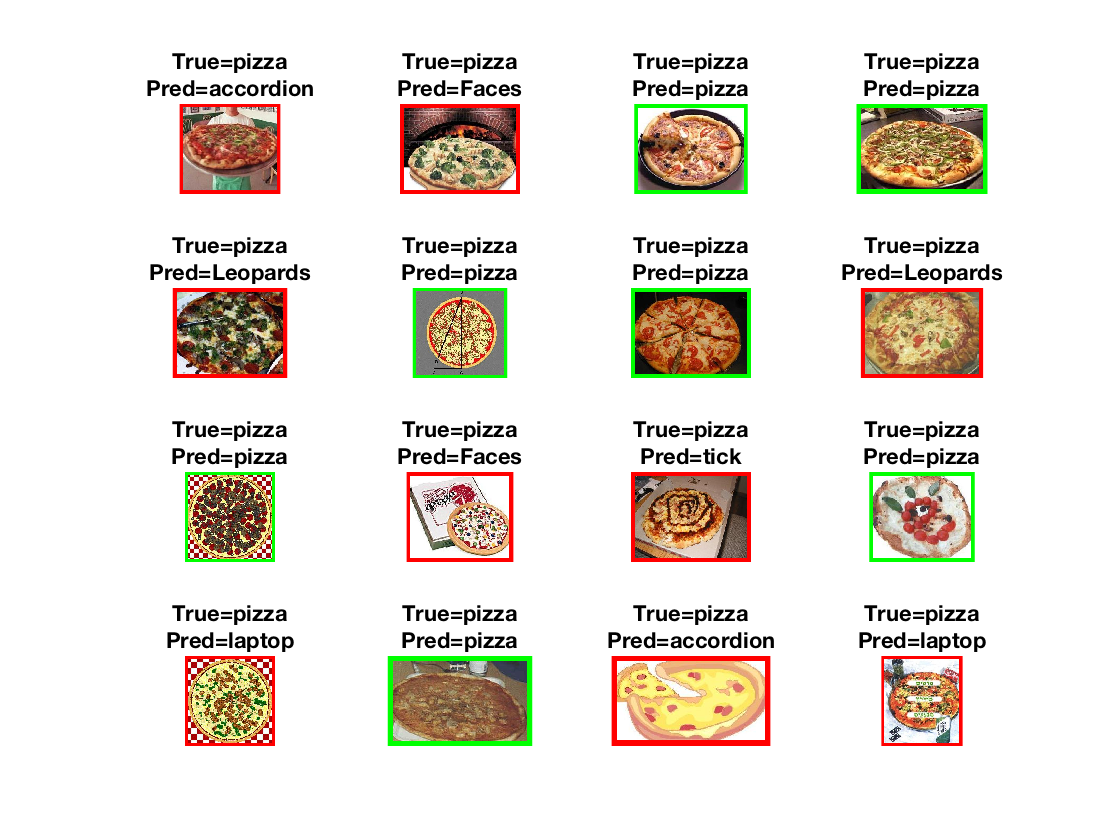

modelPath = fullfile('data','reduced-vocab-model.mat');
load(modelPath);
visualizeImgClass(imagePaths, model);

It is now observed that many of the same pizzas are now classified incorrectly. It important to have at least as many words as there are classification categories.

d) 

Explore and explain how the k-means is applied, which parameters are used, what is there meaning and what are the advantages and the limitations of the method.

Code to construct vocabulary:

% vocab = vl_kmeans(descrs, conf.numWords, 'algorithm', 'elkan', 'MaxNumIterations', 50);

The image descriptors are passed to the kmeans algorithm as the data to cluster, and the number of words passed as an argument is used to determine the number of centroids that the kmeans algorithm will cluster the data to.

The algorithm chosen in the example is the 'elkan' algorithm, which is a fast version of the 'lloyd' algorithm, using triangular inequalities to optimize it. The 'lloyd' algorithm finds evenly spaced sets of points, which is what the k-means algorithm needs to find the centroid positions.

It finds a centroid for a set of points, and then re-partitions and re-calculates the centroids. The 'MaxNumIterations' parameter limits how many times it re-calculates in the case of it not converging before hand. Convergence is determined when the centroids are re-calculated but have not changed position since the last calculation. 

The advantages of k-means is that it is unsupervised, and therefore the labels of the data do not need to be known. Also the clusters produced by k-means can be reused on new data. So providing that the k-means algorithm has been clustered on a large amount of image categories and corresponding images, it can be used to cluster new data effectively.

However, selecting the ideal cluster size can sometimes be difficult, and once a cluster size has been determined, the whole algorithm has to be re-run to calculate a new cluster size.